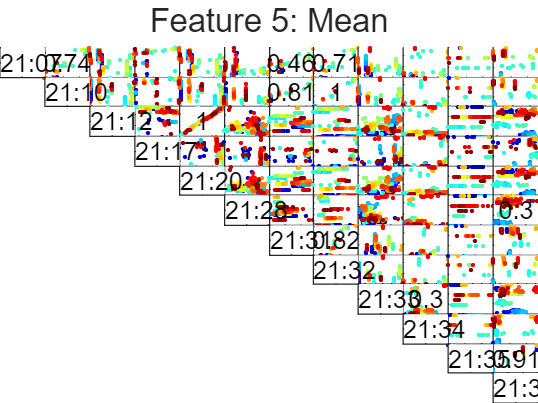

R2 =          0    0.7420    0.2918    0.1657    0.2865    0.0120    0.4556    0.7122    0.0296    0.0010    0.0003    0.0010
         0         0    0.1805    0.1424    0.1790    0.0001    0.8140    0.9953    0.0000    0.0429    0.0024    0.0058
         0         0         0    0.0987    0.9966    0.0382    0.0152    0.1748    0.1542    0.0012    0.1661    0.1183
         0         0         0         0    0.0905    0.1190    0.0862    0.1385    0.0072    0.0006    0.0000    0.0004
         0         0         0         0         0    0.0469    0.0159    0.1743    0.1528    0.0005    0.1641    0.1201
         0         0         0         0         0         0    0.0005    0.0018    0.0010    0.0458    0.2887    0.3041
         0         0         0         0         0         0         0    0.8245    0.0335    0.0991    0.0190    0.0033
         0         0         0         0         0         0         0         0    0.0003    0.0537    0.0037    0.0098
         0         0       

plotSignalVsSignal(5, FeaturesAll, featureNames, signalName, sensorNames)

fs = 5;
signalArray = [1, 2, 7, 8]; 
sig1 = FeaturesAll.(signalName(signalArray(1)) + featureNames(5));
sig2 = FeaturesAll.(signalName(signalArray(2)) + featureNames(5));
sig3 = FeaturesAll.(signalName(signalArray(3)) + featureNames(5));
sig4 = FeaturesAll.(signalName(signalArray(4)) + featureNames(5));

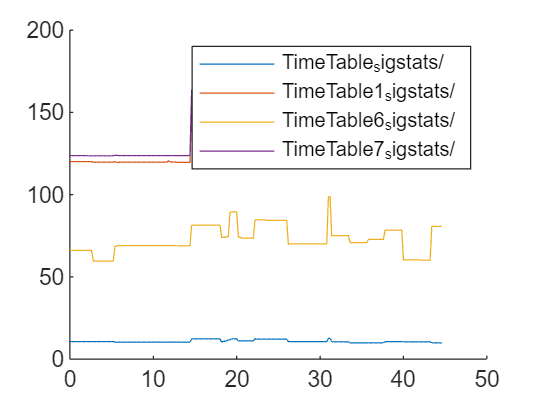

n = size(X1, 1); % Sample Size
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on;
plot(t, sig1);
plot(t, sig2);
plot(t, sig3);
plot(t, sig4);
legend(signalName(1), signalName(2), signalName(7), signalName(8));

X1 = sig1;
X2 = sig2;
X3 = sig3;

X = [X1 X2];
Y = X3;
k = 3; % Number of parameters

beta = lsqr(X, Y);

lsqr converged at iteration 2 to a solution with relative residual 0.052.


Y_est = X * beta;
sigmaEstimate = sum((Y_est - Y).^2)

sigmaEstimate = 3.2817e+03

sqrt( sigmaEstimate / n )

ans = 3.8276


%    'nAIC': Normalized Akaike's Information Criterion (default)
%            nAIC = log(det(E'*E/N)) + 2d/N
%     'AIC': Akaike's Information Criterion (raw measure)
%            AIC = N*nAIC + N*(ny*log(2*pi) + 1)
AIC = -2*(log(sigmaEstimate^2)) + 2*k

AIC = -26.3845

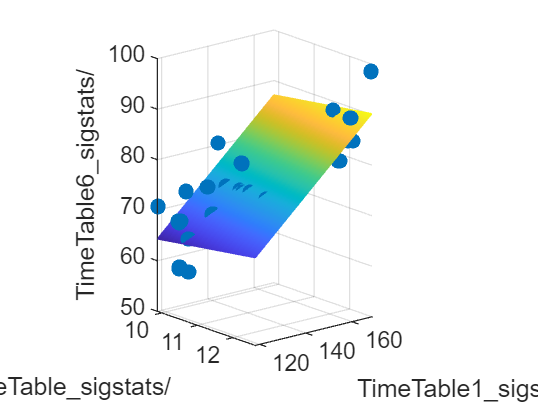

%AIC = - 2 * log L (Mk) + 2 k;

% An alternative formula for least squares regression type analyses 
% for normally distributed errors:
% https://www.statisticshowto.com/akaikes-information-criterion/
deltaAIC = 2 * k + n * log(sigmaEstimate^2);

figure();
scatter3(X1,X2,Y,'filled');
hold on;
interval1 = (max(X1) - min(X1))/20;
x1fit = min(X1):interval1:max(X1);
interval2 = (max(X1) - min(X1))/20;
x2fit = min(X2):interval2:max(X2);
[X1FIT,X2FIT] = meshgrid(x1fit, x2fit);
%YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT + b(4)*X1FIT.*X2FIT;
YFIT = beta(1).*X1FIT + beta(2).*X2FIT;
mesh(X1FIT, X2FIT, YFIT)
xlabel(signalName(signalArray(1)), 'Interpreter', 'none');
ylabel(signalName(signalArray(2)), 'Interpreter', 'none');
zlabel(signalName(signalArray(3)), 'Interpreter', 'none');
view(50,10);

X1 = sig1;
X2 = sig4;
X3 = sig3; % Y

X = [X1 X2];
Y = X3;

beta = lsqr(X, Y);

lsqr converged at iteration 2 to a solution with relative residual 0.05.


Y_est = X * beta;
sigmaEstimate = sum((Y_est - Y).^2)

sigmaEstimate = 2.9927e+03

sqrt( sigmaEstimate / n )

ans = 3.6552


deltaAIC = 2 * k + n * log(sigmaEstimate ^2)

deltaAIC = 3.5918e+03

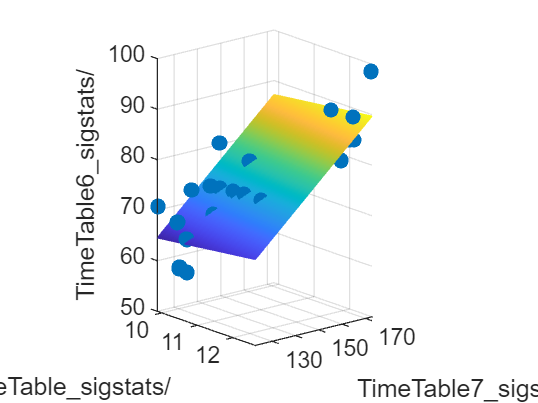


figure();
scatter3(X1,X2,Y,'filled');
hold on;
interval1 = (max(X1) - min(X1))/20;
x1fit = min(X1):interval1:max(X1);
interval2 = (max(X1) - min(X1))/20;
x2fit = min(X2):interval2:max(X2);
[X1FIT,X2FIT] = meshgrid(x1fit, x2fit);
%YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT + b(4)*X1FIT.*X2FIT;
YFIT = beta(1).*X1FIT + beta(2).*X2FIT;
mesh(X1FIT, X2FIT, YFIT)
xlabel(signalName(signalArray(1)), 'Interpreter', 'none');
ylabel(signalName(signalArray(4)), 'Interpreter', 'none');
zlabel(signalName(signalArray(3)), 'Interpreter', 'none');
view(50,10);

X1 = sig2;
X2 = sig4;
X3 = sig3;

X = [X1 X2];
Y = X3;

beta = lsqr(X, Y);

lsqr converged at iteration 2 to a solution with relative residual 0.05.


Y_est = X * beta;
sigmaEstimate = sum((Y_est - Y).^2)

sigmaEstimate = 2.9355e+03

sqrt( sigmaEstimate / n )

ans = 3.6201


deltaAIC = 2 * k + n * log(sigmaEstimate ^2)

deltaAIC = 3.5831e+03

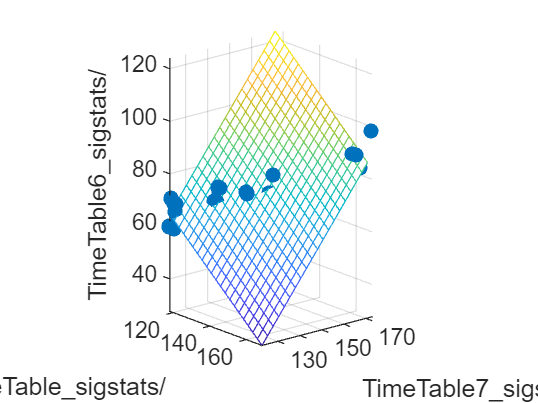


figure();
scatter3(X1,X2,Y,'filled');
hold on;
interval1 = (max(X1) - min(X1))/20;
x1fit = min(X1):interval1:max(X1);
interval2 = (max(X1) - min(X1))/20;
x2fit = min(X2):interval2:max(X2);
[X1FIT,X2FIT] = meshgrid(x1fit, x2fit);
%YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT + b(4)*X1FIT.*X2FIT;
YFIT = beta(1).*X1FIT + beta(2).*X2FIT;
mesh(X1FIT, X2FIT, YFIT)
xlabel(signalName(signalArray(1)), 'Interpreter', 'none');
ylabel(signalName(signalArray(4)), 'Interpreter', 'none');
zlabel(signalName(signalArray(3)), 'Interpreter', 'none');
view(50,10);

X1 = sig1;
X2 = sig2;
X3 = sig3;
X4 = sig4;

X = [X1 X2 X4];
Y = X3;

beta = lsqr(X, Y);

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.049.


Y_est = X * beta;
sigmaEstimate = sum((Y_est - Y).^2)

sigmaEstimate = 2.8114e+03

sqrt( sigmaEstimate / n )

ans = 3.5428


deltaAIC = 2 * k + n * log(sigmaEstimate ^2)

deltaAIC = 3.5638e+03

%X = [ones(size(x1)) x1 x2 x1.*x2];
X = [ones(size(x1)) x1 x2];
b = regress(Y,X);

%mdl = fitlm(X, Y)
%mdl.Residuals.Raw
%r2 = mdl.Rsquared.Adjusted

function [] = plotSignalVsSignal(featureIndex, FeaturesAll, featureNames, signalName, sensorNames)
    figure();
    t = tiledlayout(12,12,'TileSpacing','None', 'Padding','tight');
    title(t, "Feature " + featureIndex + ": " + featureNames(featureIndex) );
    numpoints = size(FeaturesAll.(signalName(1) + featureNames(1)), 1);
    pointidx = 1 : numpoints; 
    numOfSignals = size(signalName, 2);
    R2 = zeros(numOfSignals, numOfSignals);
    for signalIndex1 = 1:numOfSignals
        for signalIndex2 = signalIndex1:numOfSignals
            if signalIndex1 ~= signalIndex2
                sig1 = FeaturesAll.(signalName(signalIndex1) + featureNames(featureIndex));
                sig2 = FeaturesAll.(signalName(signalIndex2) + featureNames(featureIndex));
                nexttile((signalIndex1-1) * numOfSignals + signalIndex2);
                scatter(sig1, sig2, 3, pointidx, 'filled');
                colormap( jet(numpoints) );
                xticklabels({});
                yticklabels({});

                mdl = fitlm(sig1, sig2);
                R2(signalIndex1, signalIndex2) = mdl.Rsquared.Ordinary;

                DataX = interp1( [0 1], xlim(), 0.5 );
                DataY = interp1( [0 1], ylim(), 0.5 );
                if R2(signalIndex1, signalIndex2) > 0.3
                    text(DataX, DataY, num2str(R2(signalIndex1, signalIndex2), 2), 'HorizontalAlignment','center');
                end
            end
        end
    end
    % Add Labels
    for i = 1:size(sensorNames, 2)
        nexttile((i-1) * numOfSignals + i);
        str = char(sensorNames(i));
        text(0, 0.5, str(1:5));
        xticklabels({});
        yticklabels({});
    end
    R2
end